# Fill Missing Values with Unequal Spacing

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

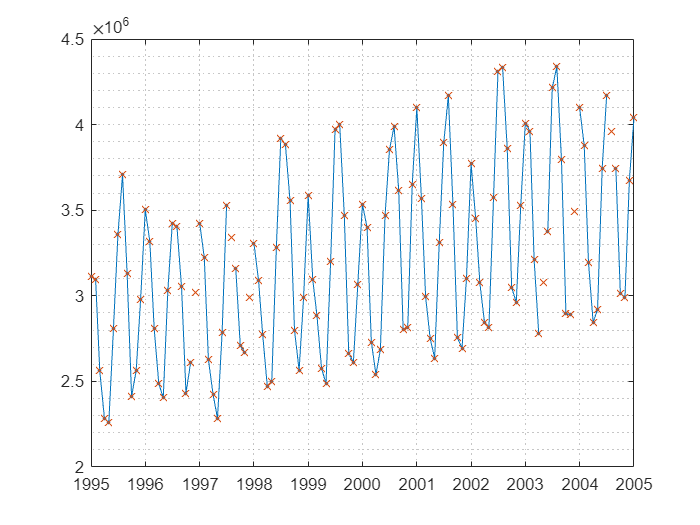

usage = table2array(readtable("../data/electricityData.xlsx", "Sheet", "usage", 'ReadVariableNames', false));
dates = table2array(readtable("../data/electricityData.xlsx", "Sheet", "dates", 'ReadVariableNames', false));
plot(dates,usage(:,1),".-")
grid minor
xlim(datetime([1995,2005],1,1))
eqfill = fillmissing(usage,"linear");
hold on
plot(dates,eqfill(:,1),"x")
hold off

## Task 1

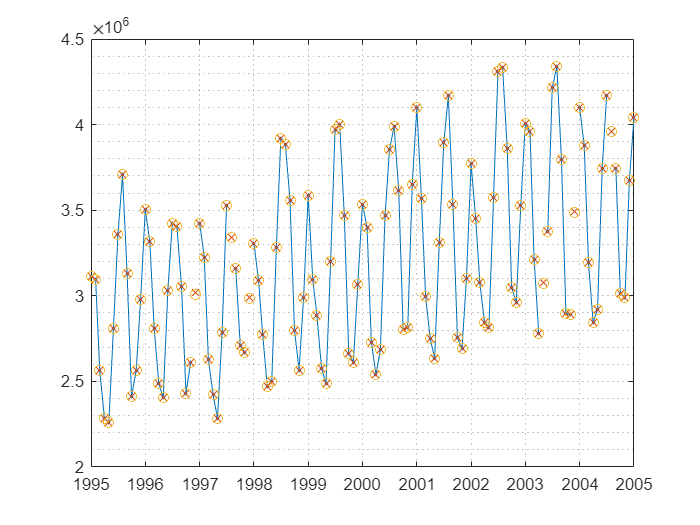

linfill = fillmissing(usage,"linear","SamplePoints",dates);
hold on
plot(dates,linfill(:,1),"o")
hold off